# Create Deep Learning Network Architecture

Script for creating the layers for a deep learning network with the following properties:

Run the script to create the layers in the workspace variable `lgraph`.

To learn more, see [Generate MATLAB Code From Deep Network Designer](matlab:helpview('deeplearning','generate_matlab_code')).

Auto-generated by MATLAB on 16-Sep-2022 09:45:04

## Create Layer Graph

Create the layer graph variable to contain the network layers.

lgraph = layerGraph();

## Add Layer Branches

Add the branches of the network to the layer graph. Each branch is a linear array of layers.

tempLayers = [
    imageInputLayer([227 227 3],"Name","imageinput")
    convolution2dLayer([5 7],32,"Name","conv_1","Padding","same")
    instanceNormalizationLayer("Name","instancenorm_1")
    reluLayer("Name","relu_1")
    convolution2dLayer([3 3],32,"Name","conv_2","Padding","same","Stride",[2 2])
    instanceNormalizationLayer("Name","instancenorm_2")
    reluLayer("Name","relu_2")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([3 3],32,"Name","conv_3","Padding","same")
    instanceNormalizationLayer("Name","instancenorm_3")
    reluLayer("Name","relu_3")
    convolution2dLayer([3 3],32,"Name","conv_4","Padding","same")
    instanceNormalizationLayer("Name","instancenorm_4")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","addition")
    transposedConv2dLayer([3 3],32,"Name","transposed-conv","Cropping","same","Stride",[2 2])
    instanceNormalizationLayer("Name","instancenorm_5")
    reluLayer("Name","relu_4")
    convolution2dLayer([5 7],32,"Name","conv_5","Padding","same")
    tanhLayer("Name","tanh")
    pixelClassificationLayer("Name","pixel-class")];
lgraph = addLayers(lgraph,tempLayers);

% clean up helper variable
clear tempLayers;

## Connect Layer Branches

Connect all the branches of the network to create the network graph.

lgraph = connectLayers(lgraph,"relu_2","conv_3");
lgraph = connectLayers(lgraph,"relu_2","addition/in2");
lgraph = connectLayers(lgraph,"instancenorm_4","addition/in1");

## Plot Layers

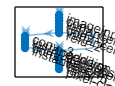

plot(lgraph);